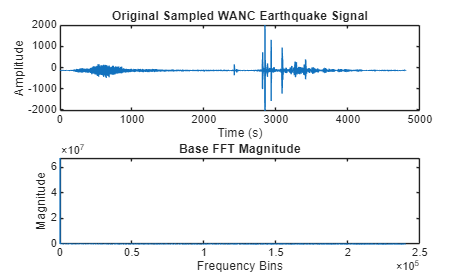

sac_file = 'WANC_SHZ_2004_361_01-10-00.SAC'; 
[data, header] = readsac(sac_file);
ts = header.DELTA;
fs = 1/ts;

N = length(data);
t = (0:N-1) * ts; % Time vector for plotting

%Earthquake Data Plot
figure(1);
subplot(2,1,1);
plot(t, data);
title('Original Sampled WANC Earthquake Signal');
xlabel('Time (s)');
ylabel('Amplitude');


X_orig = fft(data);
freq_bins = (0:N-1); 

%Base FFT Plot
subplot(2,1,2);
plot(freq_bins(1:floor(N/2)), abs(X_orig(1:floor(N/2))));
title('Base FFT Magnitude');
xlabel('Frequency Bins');
ylabel('Magnitude');

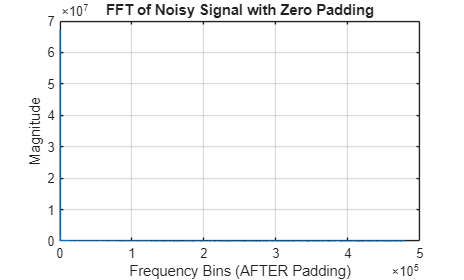

% Noise and Zero Padding
% Gaussian white noise
noise_level = 0.02; 
data_noisy = data + noise_level * randn(size(data));

% zero padding
pad_length = N; 
data_padded = [data_noisy; zeros(pad_length, 1)];
N_padded = length(data_padded);

% FFT of padded and noisy signal
X_padded = fft(data_padded);
freq_bins_padded = (0:N_padded-1); 

%FFT plot now with noise
figure(2);
plot(freq_bins_padded(1:floor(N_padded/2)), abs(X_padded(1:floor(N_padded/2))));
title('FFT of Noisy Signal with Zero Padding');
xlabel('Frequency Bins');
ylabel('Magnitude');
grid on;

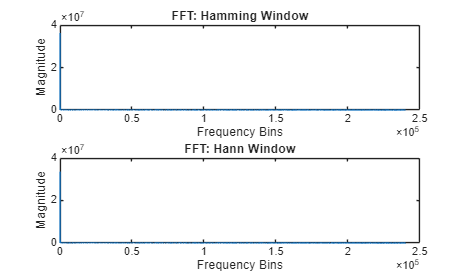

% Hamming and Hann windows via Signal Toolbox
win_hamming = hamming(N);
win_hann = hann(N);

data_hamming = data .* win_hamming;
data_hann = data .* win_hann;

% FFTs for windowed results
X_hamming = fft(data_hamming);
X_hann = fft(data_hann);

figure(3);
subplot(2,1,1);
plot(freq_bins(1:floor(N/2)), abs(X_hamming(1:floor(N/2))));
title('FFT: Hamming Window');
xlabel('Frequency Bins');
ylabel('Magnitude');

subplot(2,1,2);
plot(freq_bins(1:floor(N/2)), abs(X_hann(1:floor(N/2))));
title('FFT: Hann Window');
xlabel('Frequency Bins');
ylabel('Magnitude');